## **Time Series Analysis on Adj. Close from ^BVSP using Matlab **

Time Series forecast the values of future time steps of a sequence, that trains a sequence-to-sequence regression LSTM network. The responses are the training sequences with values shifted by one time step. At each time step of the input sequence, the LSTM network learns to predict the value of the next time step.

The dataset can be found from Yahoo Finance, here: 

[^BVSP](https://finance.yahoo.com/quote/%5EBVSP/history?period1=749102400&period2=1569556800&interval=1d&filter=history&frequency=1d)

^BVSP or IBOVESPA is a Billion Brazil Real Money accumulation by year Media industries index. Its index number represents the present value of a portfolio begun on 2 January 1968, with a starting value of 100 and taking into account share price increases plus the reinvestment of all dividends, subscription rights that the constant's bonus stocks received.

The index is composed by a theoretical portfolio with the stocks that accounted for 80% of the volume traded in the last 12 months and that were traded at least on 80% of the trading days. It's revised quarterly, in order to keep its representativeness of the volume traded and in average the components of Ibovespa represent 70% of the all the stock value traded.

____________________________________________________

## Load Sequence Data

Loading ^BVSP contains a single time series Adj. Close, with time steps corresponding to months and values corresponding to market prices. 

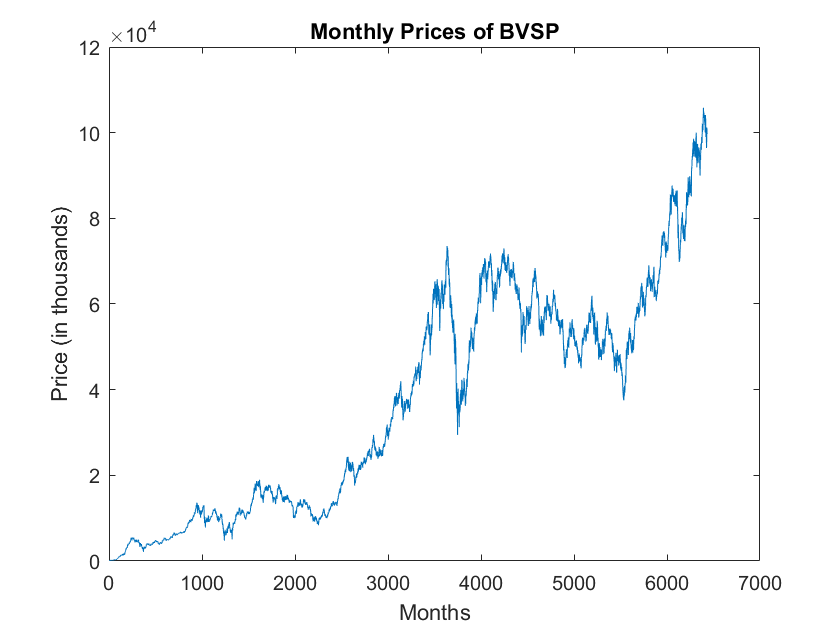

figure
plot(BVSP2)
xlabel("Months")
ylabel("Price (in thousands)")
title("Monthly Prices of BVSP")

Partitioning the training and test data. The data is trained on the first 90% of the sequence and tested on the last 10%.

numTimeStepsTrain = floor(0.9*numel(BVSP2));

dataTrain = BVSP2(1:numTimeStepsTrain+1);
dataTest = BVSP2(numTimeStepsTrain+1:end);

## Standardize Data

To best fit the data, standardize the training data to have zero mean and unit variance. When creating predictions, standardize the test data using the same parameters as the training data.

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

## Pedictors and Responses

To forecast the values of future time steps of a sequence, the responses are specified to the training sequences with values shifted by one time step. At each time step of the input sequence, the LSTM network learns to predict the value of the next time step. The predictors are the training sequences without the final time step.

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

## **Define LSTM Network Architecture**

Create an LSTM regression network. Specify the LSTM layer to have 200 hidden units.

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 200;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

Specifing the training options. The solver is set to `'adam'` and trained for 250 epochs. To prevent the gradients from exploding, the gradient threshold is set to 1. The initial learning rate is 0.005, then dropped after 125 epochs by multiplying by a factor of 0.2.

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

## Train LSTM Network

Train the LSTM network with the specified training options by using `trainNetwork`.

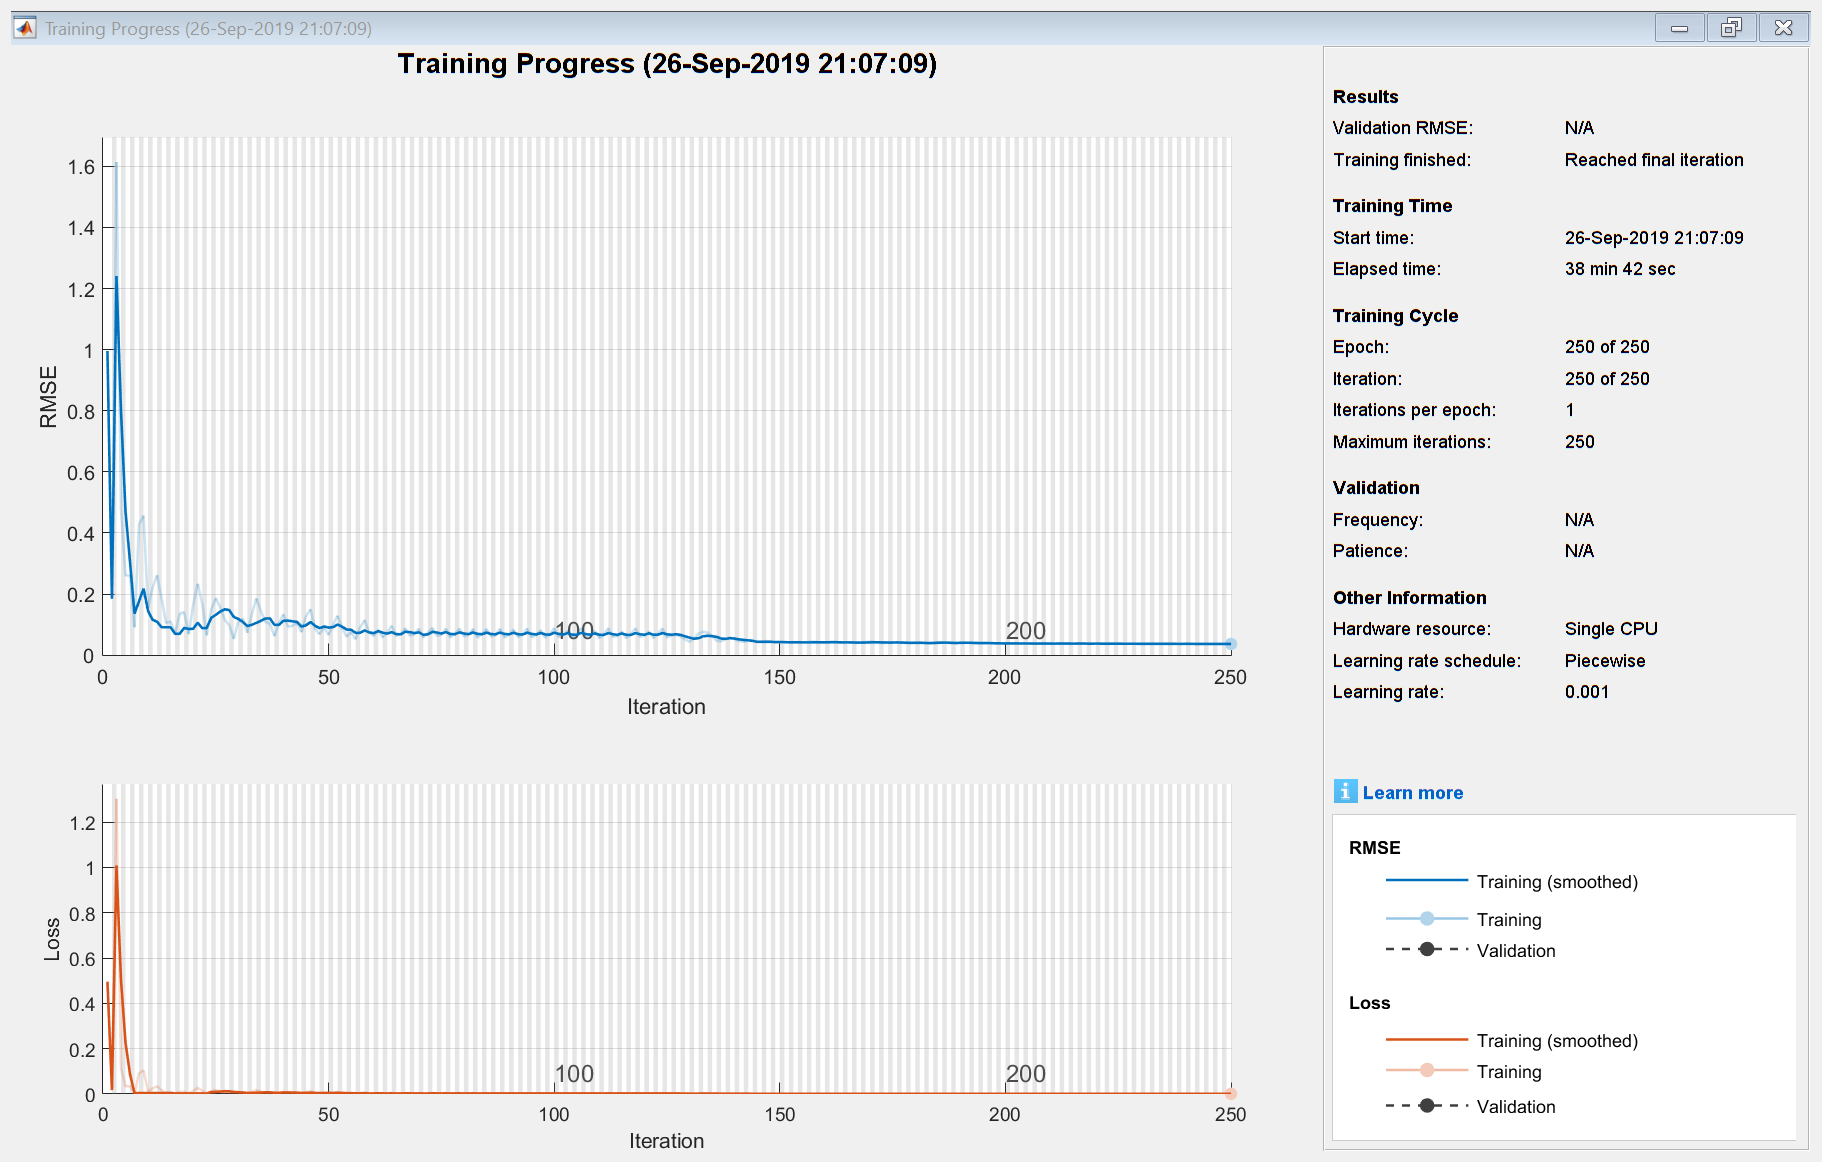

net = trainNetwork(XTrain,YTrain,layers,options);

## Forecast Future Time Steps

 For each prediction, use the previous prediction as input to the function. The data is standardized to the test data using the same parameters as the training data.

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

To initialize the network state, first predict on the training data `XTrain`. Next, make the first prediction using the last time step of the training response `YTrain(end)`. Loop over the remaining predictions and input the previous prediction to `predictAndUpdateState`.

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

Unstandardize the predictions using the parameters calculated earlier.

YPred = sig*YPred + mu;

The training progress plot reports the root-mean-square error (RMSE) calculated from the standardized data. Calculate the RMSE from the unstandardized predictions.

YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
1.1618e+09

Plot the training time series with the forecasted values.

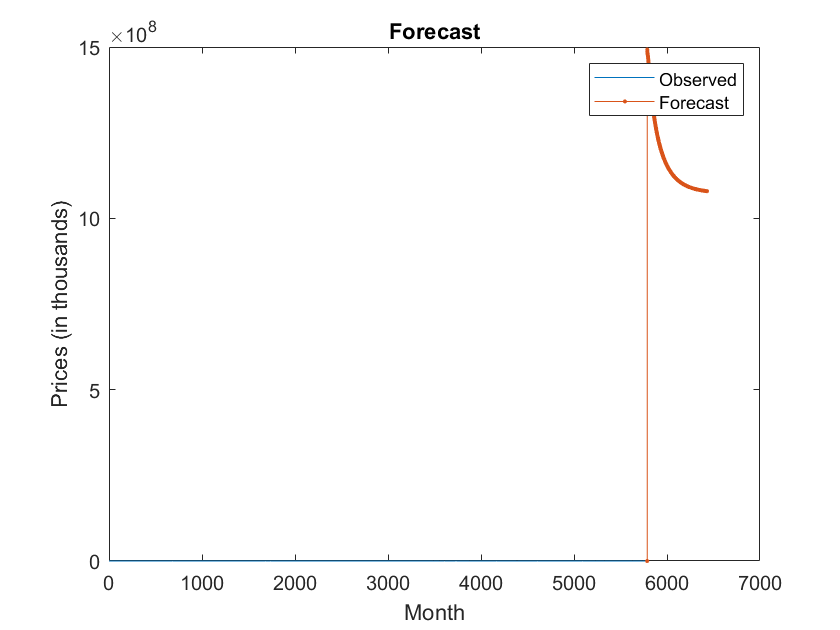

figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[BVSP2(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Prices (in thousands)")
title("Forecast")
legend(["Observed" "Forecast"])

Compare the forecasted values with the test data.

figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[BVSP2(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Prices (in thousands)")
title("Forecast")
legend(["Observed" "Forecast"])

## Update Network State with Observed Values

If you have access to the actual values of time steps between predictions, then you can update the network state with the observed values instead of the predicted values.

First, initialize the network state. To make predictions on a new sequence, reset the network state using `resetState`. Resetting the network state prevents previous predictions from affecting the predictions on the new data. Reset the network state, and then initialize the network state by predicting on the training data.

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

Predict on each time step. For each prediction, predict the next time step using the observed value of the previous time step. Set the `'ExecutionEnvironment'` option of `predictAndUpdateState` to `'cpu'`.

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

Unstandardize the predictions using the parameters calculated earlier.

YPred = sig*YPred + mu;

Calculate the root-mean-square error (RMSE).

rmse = sqrt(mean((YPred-YTest).^2))

rmse = 1.8371e+09

Compare the forecasted values with the test data.

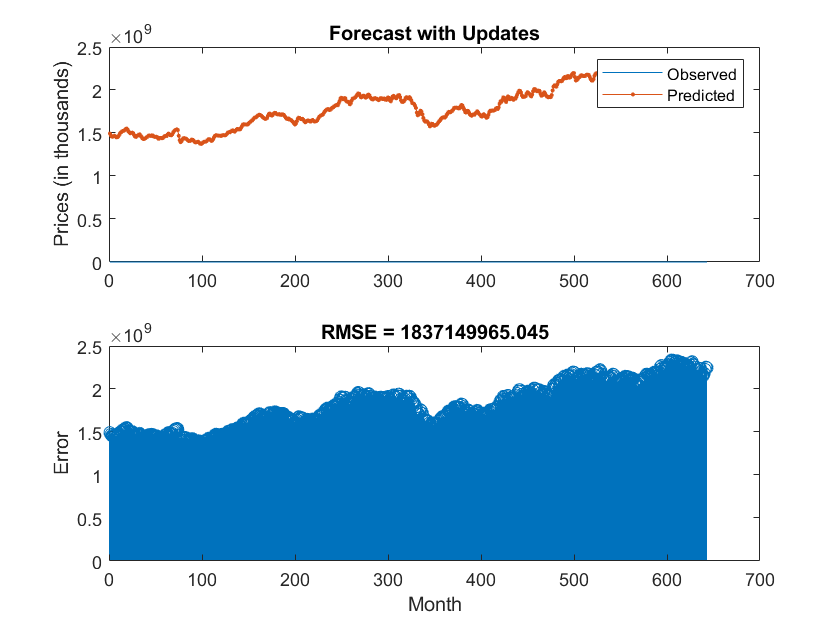

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Prices (in thousands)")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

Here, the predictions are as accurate when updating the network state with the observed values instead of the predicted values.

****Reference: MathWorks***